% global ecModel;
% global fit_data;
% global kcat_list;

load('reaction_kcat_list.mat');
text = fileread('optimization_data_1 - 副本.json');
fit_data = jsondecode(text);
% load('ecModel.mat');
ecModel = setParam(ecModel, 'lb', 'EX_glc__D_e', 0);
% load("start_kcats.mat")
% load("solution.mat")
start_kcats = getkcatfromModel(ecModel, kcat_list);
max_change_factor = 100;
lower_bounds = [];
upper_bounds = [];
for i = 1:numel(start_kcats)
    lower_bounds(i) = (start_kcats(i)) / max_change_factor;
    upper_bounds(i) = (start_kcats(i)) * max_change_factor;
end
lower_bounds = lower_bounds';
upper_bounds = upper_bounds';


f = @(x)objectiveFcn_1(x, ecModel, fit_data, kcat_list);

    0.2156

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

    0.2156

  

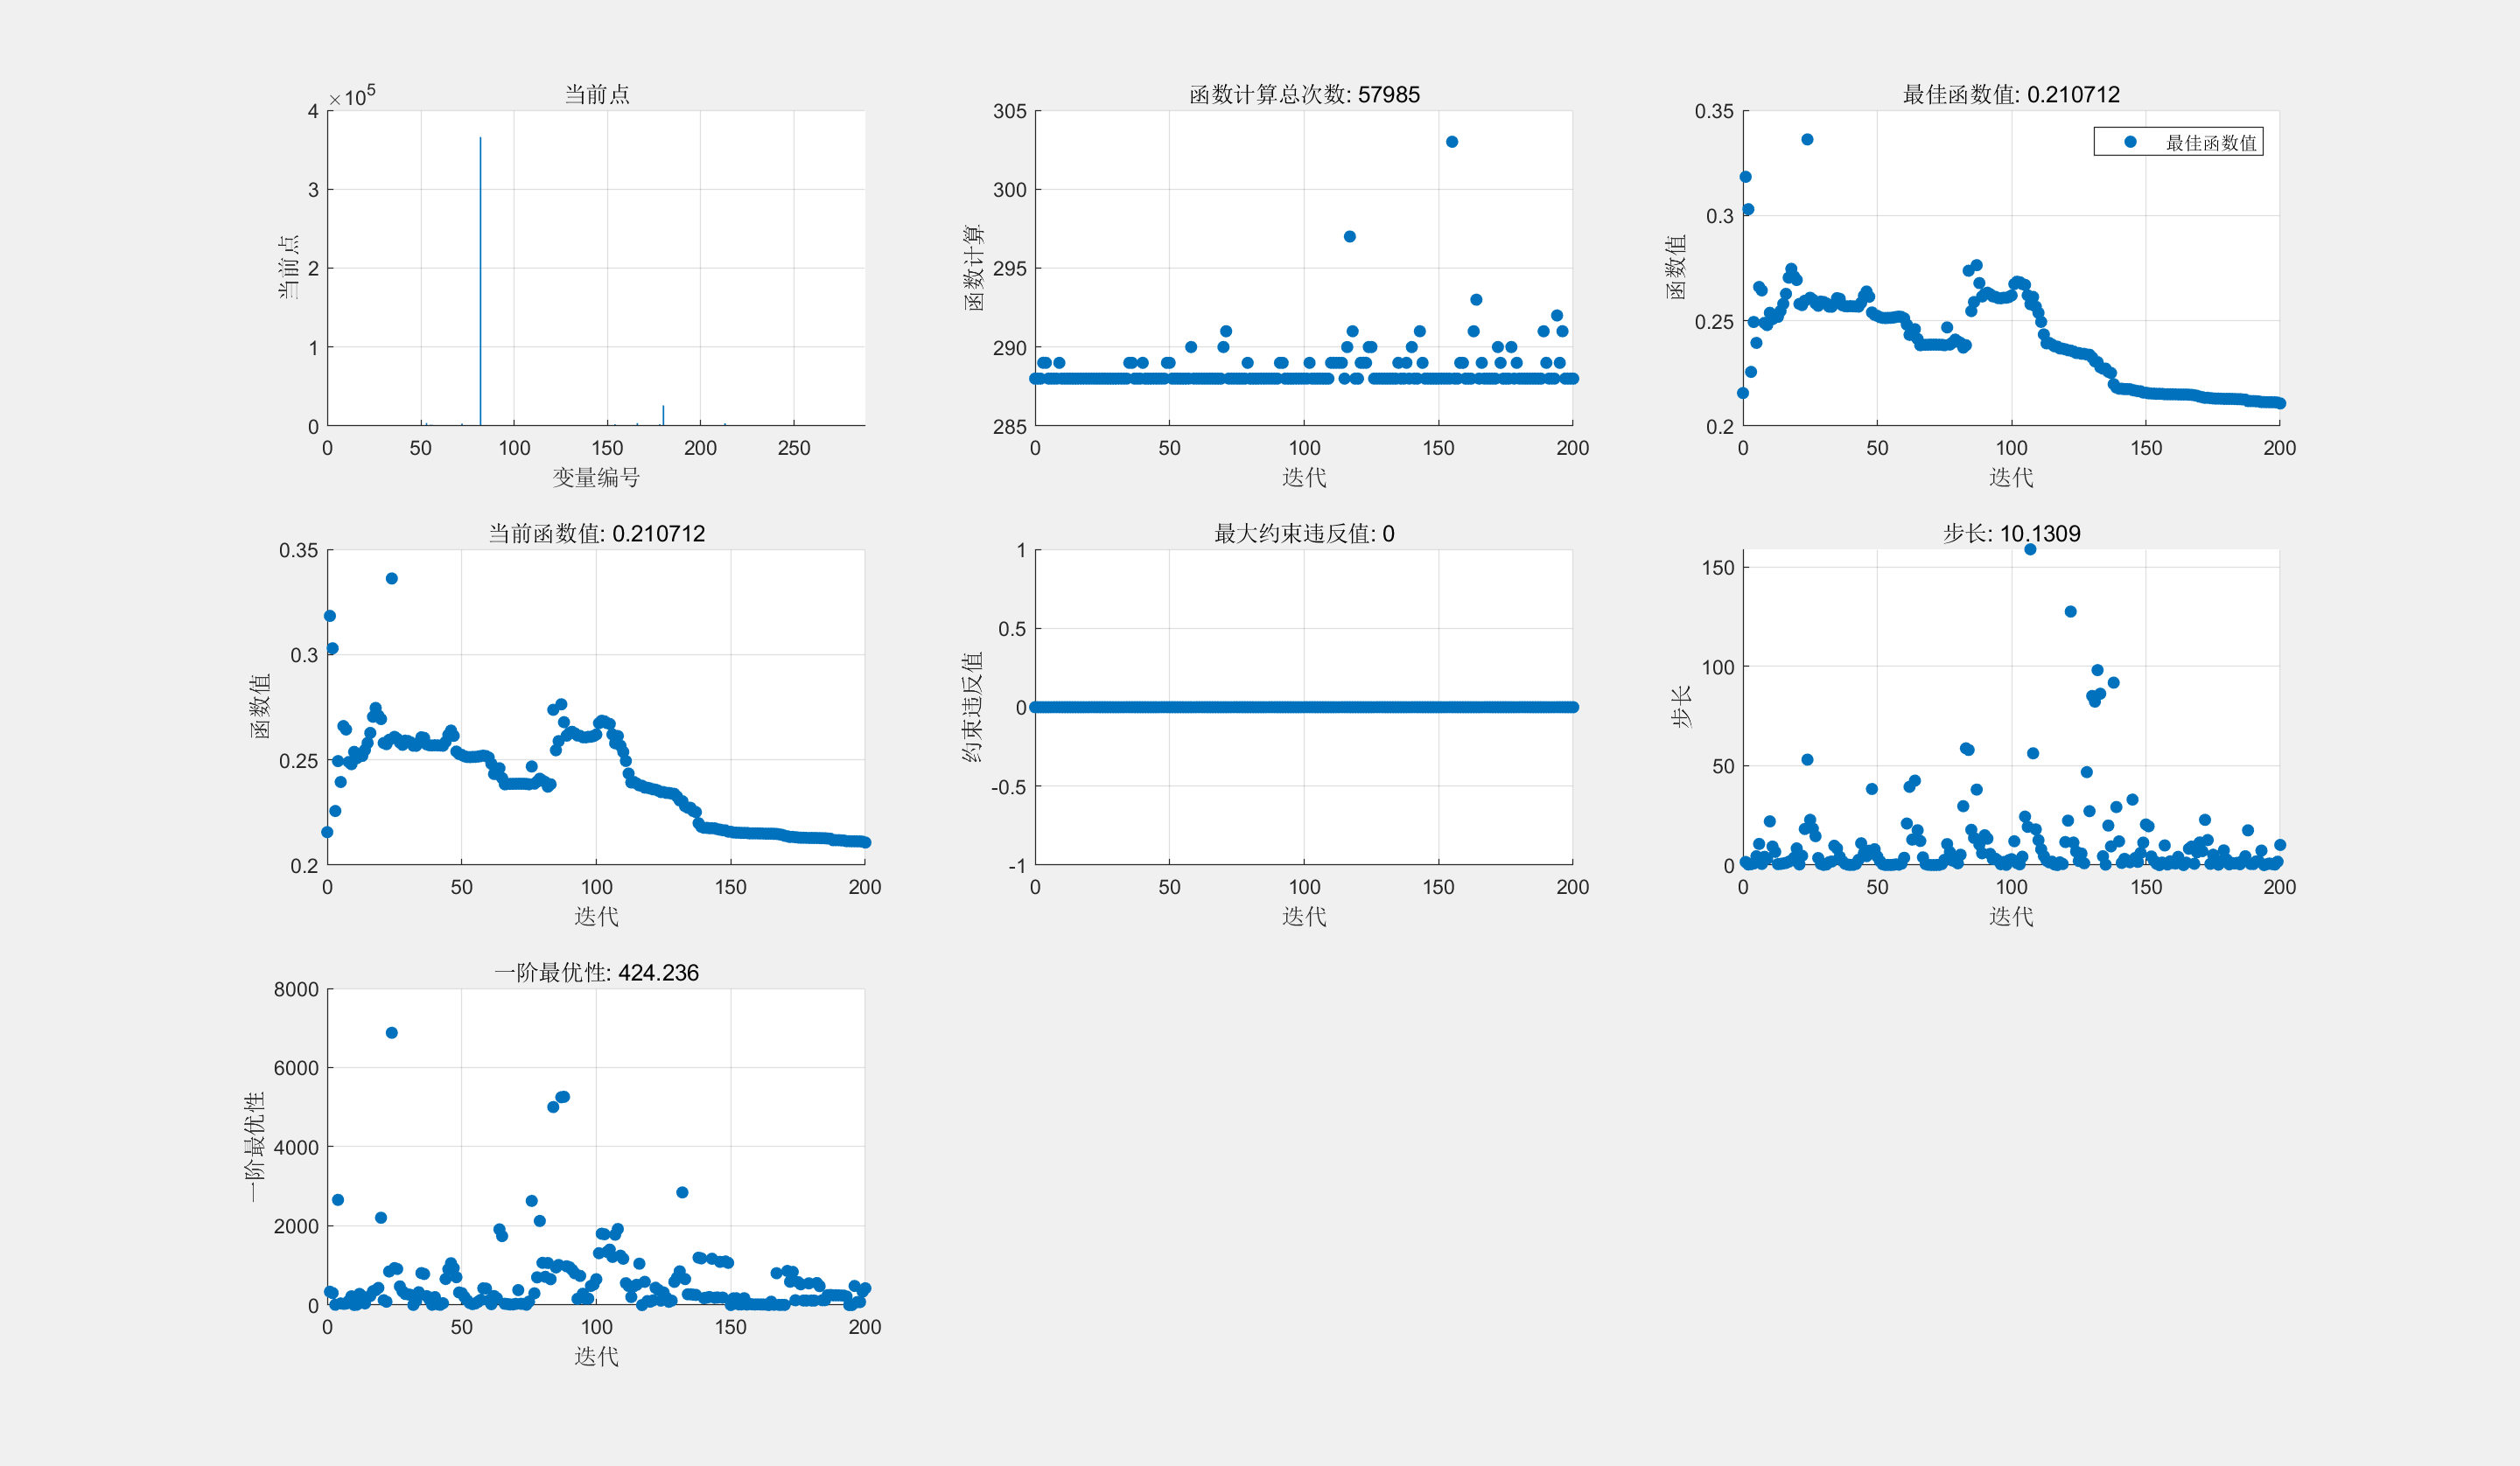

% 设置非默认求解器选项
options = optimoptions("fmincon","MaxIterations",200,...
    "MaxFunctionEvaluations",30000000,"UseParallel",true,"Display","iter",...
    "PlotFcn",["optimplotx","optimplotfunccount","optimplotfvalconstr",...
    "optimplotfval","optimplotconstrviolation","optimplotstepsize",...
    "optimplotfirstorderopt"]);

% 求解
[solution,objectiveValue] = fmincon(f,solution,[],[],[],[],repmat(-Inf,...
    size(solution)),Inf(size(solution)),[],options);

% 清除变量
clearvars options